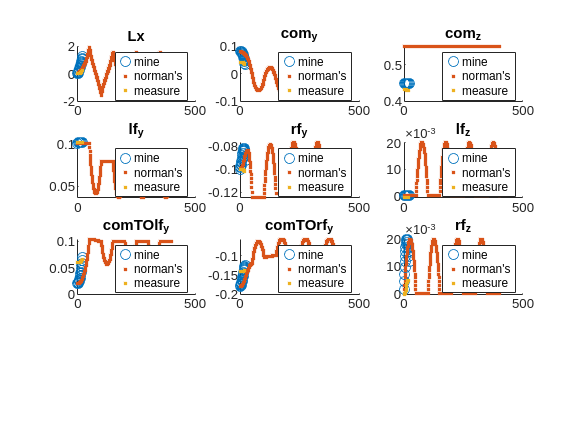

clear; clc; close all
norman_dir = "/home/ldsc/ros2_ws/src/bipedal_floating_description/bipedal_floating_description/alip軌跡驗證/祐華學長ALIP/";

% ref_data
data = readmatrix('real_planning.csv');
data = data(2:end,1:end);

com_x = data(:,  2);   % com 的 x
com_y = data(:,  3);   % com 的 y
com_z = data(:,  4);   % com 的 z
lf_x  = data(:,  5);   % lf 的 x
lf_y  = data(:,  6);   % lf 的 y
lf_z  = data(:,  7);   % lf 的 z
rf_x  = data(:,  8);   % rf 的 x
rf_y  = data(:,  9);   % rf 的 y
rf_z  = data(:, 10);   % rf 的 z
x     = data(:, 11);   % var的x
y     = data(:, 12);   % var的y
Ly    = data(:, 13);   % Ly
Lx    = data(:, 14);   % Lx

% measure_data
data_m = readmatrix('real_measure.csv');
data_m = data_m(2:end,1:end);

com_x_m = data_m(:,  2);  % com 的 x
com_y_m = data_m(:,  3);  % com 的 y
com_z_m = data_m(:,  4);  % com 的 z
lf_x_m  = data_m(:,  5);  % lf 的 x
lf_y_m  = data_m(:,  6);  % lf 的 y
lf_z_m  = data_m(:,  7);  % lf 的 z
rf_x_m  = data_m(:,  8);  % rf 的 x
rf_y_m  = data_m(:,  9);  % rf 的 y
rf_z_m  = data_m(:, 10);  % rf 的 z
x_m     = data_m(:, 11);  % var的x
y_m     = data_m(:, 12);  % var的y
Ly_m    = data_m(:, 13);  % Ly
Lx_m    = data_m(:, 14);  % Lx

com_norman = readmatrix(norman_dir + "CX_ref.csv");
lf_norman  = readmatrix(norman_dir + "LX_ref.csv");
rf_norman  = readmatrix(norman_dir + "RX_ref.csv");

com_x_norman = com_norman(:,1);
com_y_norman = com_norman(:,2);
com_z_norman = com_norman(:,3);
lf_x_norman  = lf_norman(:,1);
lf_y_norman  = lf_norman(:,2);
lf_z_norman  = lf_norman(:,3);
rf_x_norman  = rf_norman(:,1);
rf_y_norman  = rf_norman(:,2);
rf_z_norman  = rf_norman(:,3);
x_norman     = readmatrix(norman_dir + "xc_ref.csv");
y_norman     = readmatrix(norman_dir + "yc_ref.csv");
Ly_norman    = readmatrix(norman_dir + "ly_ref.csv");
Lx_norman    = readmatrix(norman_dir + "lx_ref.csv");

figure;
labels =       {"Lx"      , "com_y"      , "com_z"      , "lf_y"      ,  "rf_y"      , "lf_z"      , "comTOlf_y"                , "comTOrf_y"                 ,"rf_z"      };
data_vars    = { Lx       ,  com_y       ,  com_z       ,  lf_y       ,   rf_y       ,  lf_z       ,  lf_y        - com_y       ,  rf_y        - com_y        , rf_z       };
measure_vars = { Lx_m     ,  com_y_m     ,  com_z_m     ,  lf_y_m     ,   rf_y_m     ,  lf_z_m     ,  lf_y_m      - com_y_m     ,  rf_y_m      - com_y_m      , rf_z_m     };
norman_vars  = { Lx_norman,  com_y_norman,  com_z_norman,  lf_y_norman,   rf_y_norman,  lf_z_norman,  lf_y_norman - com_y_norman,  rf_y_norman - com_y_norman , rf_z_norman};

for i = 1:length(labels)
    subplot(4, 3, i);
    hold on;

    plot(data_vars{i}, "o");
    plot(norman_vars{i}, ".");
    plot(measure_vars{i}, ".");
    
    title(labels{i});
    legend("mine", "norman's", "measure");
    hold off;
end